# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.2 二维绘图

#### 2.2.4 复杂函数曲线之间填充

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

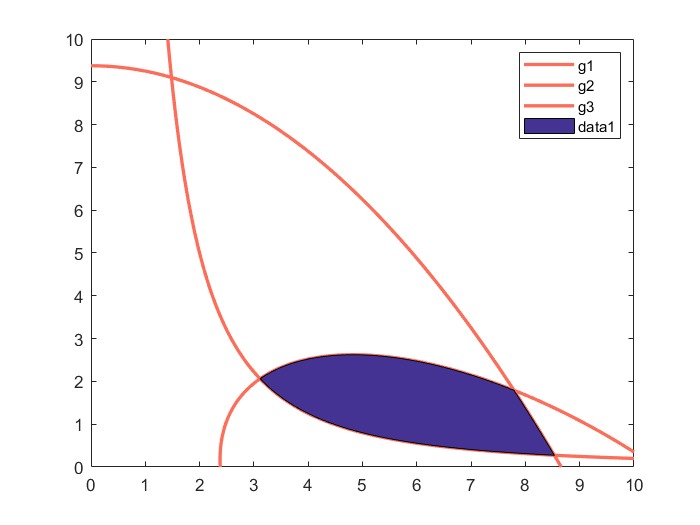

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();
% 常规思路
figure;
% 这是三个方程
g1 = @(x,y) 1 - x.^2.*y/20;
g2 = @(x, y) 1 - (x+y-5).^2/30 - (x-y-12).^2/120;
g3 = @(x, y) 1 - 80./(x.^2 + 8*y + 5);
% 把他们的图像画出来
h1 = fimplicit(g1, [0, 10], 'LineWidth', 2, 'Color', all_colors(1, :));
hold on
h2 = fimplicit(g2, [0, 10], 'LineWidth', 2, 'Color', all_colors(1, :));
h3 = fimplicit(g3, [0, 10], 'LineWidth', 2, 'Color', all_colors(1, :));
legend('g1', 'g2', 'g3');
% 问题来了，这个 y 值怎么确定
x1 = h1.XData;
y1 = h1.YData;
x2 = h2.XData;
y2 = h2.YData;
x3 = h3.XData;
y3 = h3.YData;
% 发现 x1, x2 是从大到小的，逆序搞一下
x1 = fliplr(x1);
x2 = fliplr(x2);
y1 = fliplr(y1);
y2 = fliplr(y2);
% 接下来，确定相交区域，主要看这三个关键点：g1-g2, g1-g3, g2-g3
% 数据长度不一样，难搞了，借助【数据提示】功能吧
pt1 = [3.11069, 2.06667];
pt2 = [8.53623, 0.266667];
pt3 = [7.7847, 1.8];
% 确定三个范围
idx1 = find(x1 >= pt1(1) & x1 < pt2(1));
idx2 = find(x2 >= pt1(1) & x2 < pt3(1));
idx3 = find(x3 >= pt3(1) & x3 < pt2(1));
x1 = x1(idx1);
x2 = x2(idx2);
x3 = x3(idx3);
y1 = y1(idx1);
y2 = y2(idx2);
y3 = y3(idx3);
% 一定要是一个闭环
xFill = [x1, fliplr(x3), fliplr(x2)];
yFill = [y1, fliplr(y3), fliplr(y2)];
fill(xFill, yFill, all_colors(6, :));
hold off

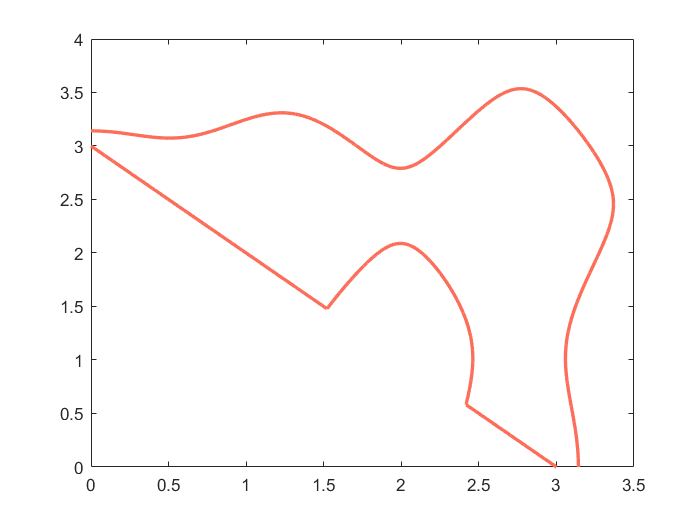

% 高级点的做法
figure;
g1 = @(x, y) -x .* sin(4 * x) - 1.1 * y .* sin(2 * y);
g2 = @(x, y) x + y - 3;
h = fimplicit(@(x, y) min(g1(x, y), g2(x, y)), [0 3.5 0 4], 'LineWidth', 2, ...
    'Color', all_colors(1, :), 'MeshDensity', 1000);

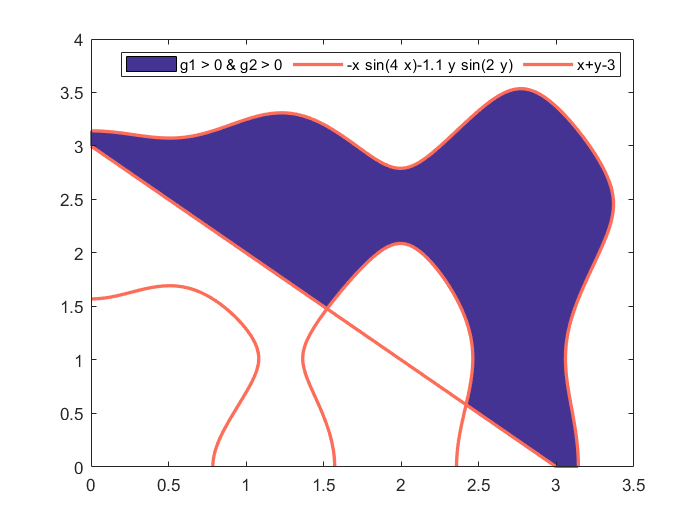

fill(rmmissing(h.XData), rmmissing(h.YData), all_colors(6, :), 'DisplayName', 'g1 > 0 & g2 > 0');
hold on
fimplicit({g1, g2}, [0 3.5 0 4], 'LineWidth', 2, 'Color', all_colors(1, :));
hold off
legend('NumColumns', 3)